Lecture14Matlab

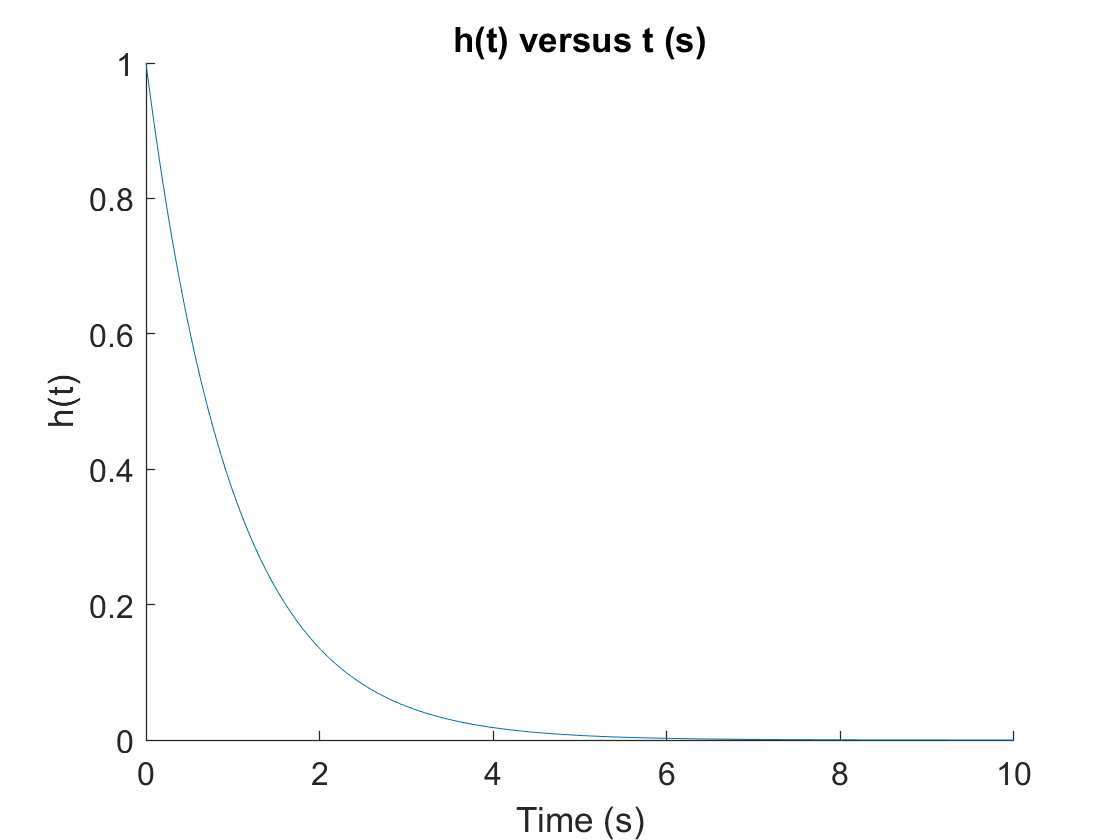

% Calculate impuse response  
a=[1 1]; b = [1];
t = 0:0.01:10;
y = impulse(b,a,t);
plot(t,y)
ax = gca;
set(gca, 'box','off');
set(ax, 'FontSize', 12);
xlabel('Time (s)')
ylabel('h(t)')
title('h(t) versus t (s)')

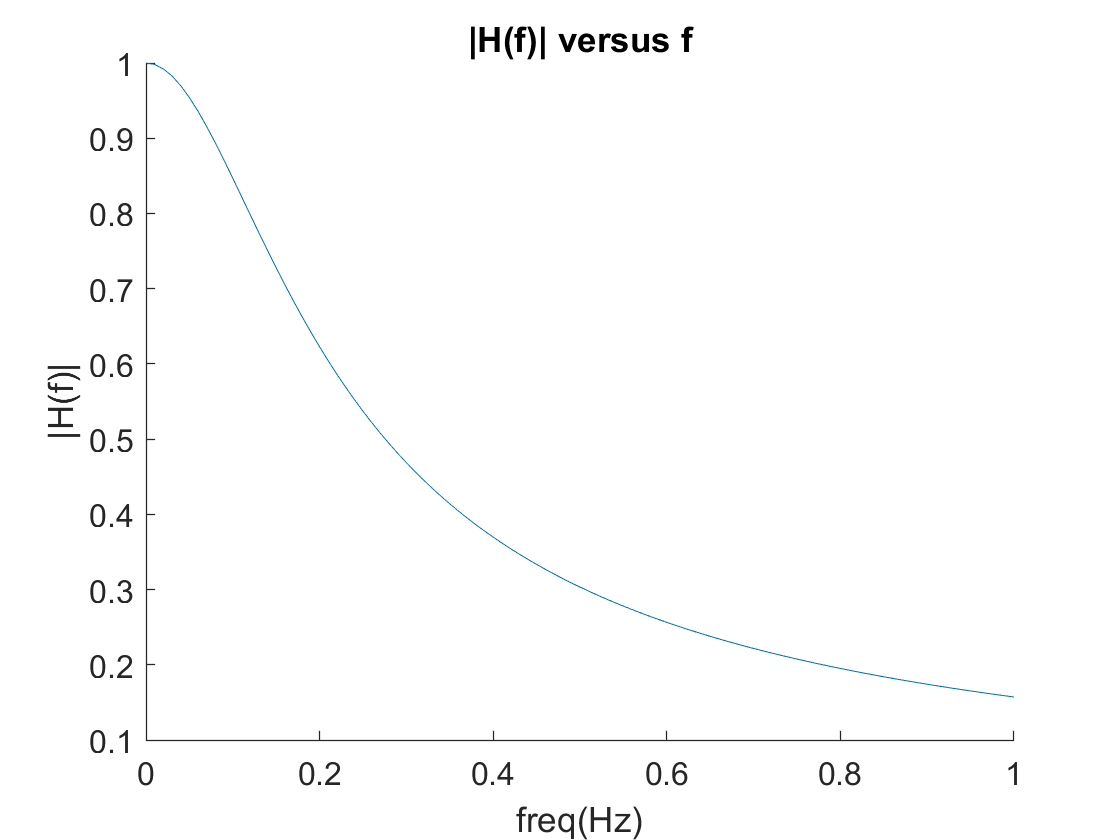

% Calculate frequency response
f=0:0.01:1;
w=2*pi*f;
H=freqs(b,a,w);
plot(f,abs(H));
ax = gca;
set(gca, 'box','off');
set(ax, 'FontSize', 12);
xlabel('freq(Hz)')
ylabel('|H(f)|')
title('|H(f)| versus f')

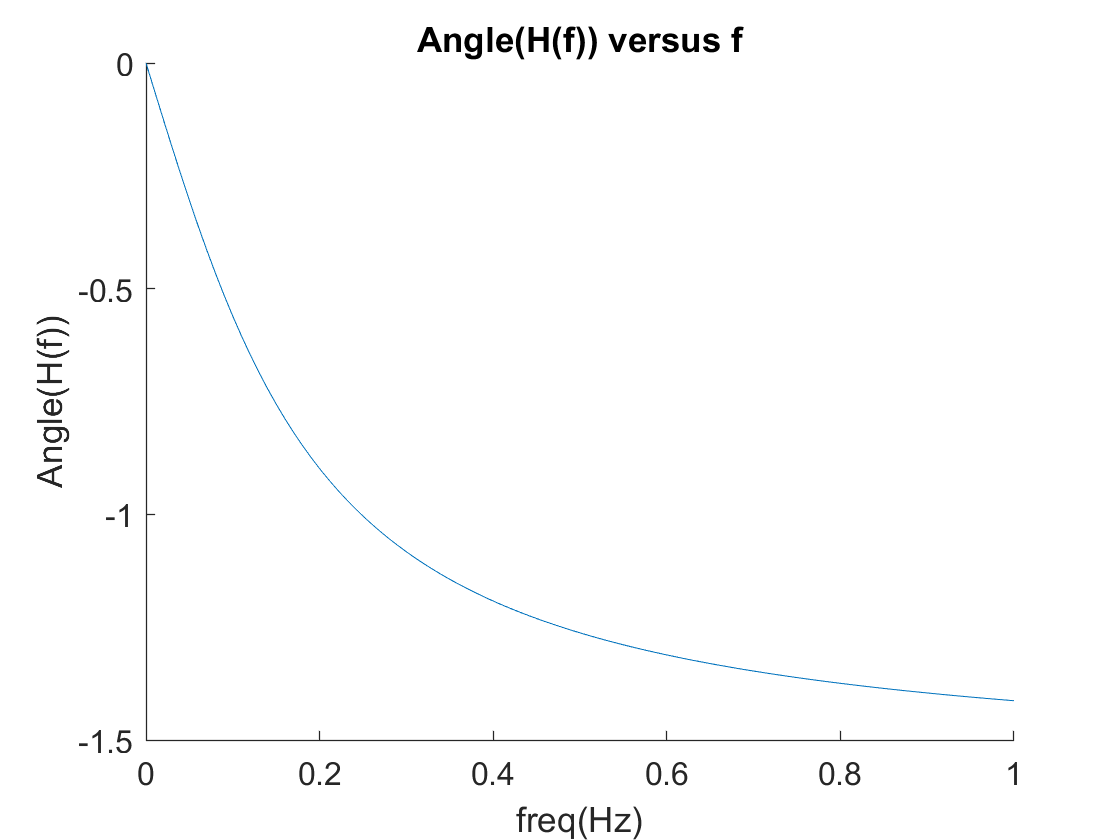

plot(f,angle(H))
ax = gca;
set(gca, 'box','off');
set(ax, 'FontSize', 12);
xlabel('freq(Hz)')
ylabel('Angle(H(f))')
title('Angle(H(f)) versus f')